# Optimization Method Project 2

# Author: Ruoxin WANG

# Date: 2023/05/04

# Section 1

- Newton's Method

            (Note that here I just put code here to display)

% function [x, k, y_opt] = newton(f, x0, tol)
%     % define the maximum iteration time.
%     max_iter = 500;
%     % initialize x using x0, the initial point.
%     x = x0;
%     % counter -- time of iteration.
%     k = 0;
%     
%     % find gradient and hessian matrix.
%     syms x1 x2
%     vars = [x1; x2];
%     % calculate gradient and hessian function of f.
%     grad = matlabFunction(gradient(f(vars), vars));
%     hess = matlabFunction(hessian(f(vars), vars));
%     
%     % iteration.
%     while norm(grad(x(1), x(2))) > tol && k < max_iter
%         % for this iteration, calculate gradient and hessian value.
%         g = grad(x(1), x(2));
%         h = hess(x(1), x(2));
%         % calculate update term.
%         %s = -h \ g;
%         s = -inv(h) * g;
%         alpha = 1;
%         x = x + s*alpha;
%         k = k + 1;
%     end
%     y_opt = f(x);
% end

2. Newton's Method with Backtracking Line Search Method

% function [x, k, y_opt] = newton_backtracking(f, x0, tol)
%     max_iter = 500;
%     x = x0;
%     % counter -- time of iteration.
%     k = 0;
%     
%      % find gradient and hessian matrix.
%     syms x1 x2
%     vars = [x1; x2];
%     % calculate gradient and hessian function of f.
%     grad = matlabFunction(gradient(f(vars), vars));
%     hess = matlabFunction(hessian(f(vars), vars));
%     
%     % iteration.
%     while norm(grad(x(1), x(2))) > tol && k < max_iter
%         alpha = 1;
%         % for this iteration, calculate gradient and hessian value.
%         g = grad(x(1), x(2));
%         h = hess(x(1), x(2));
%         % calculate update term.
%         %s = -h \ g;
%         s = -inv(h) * g;
%         x_temp = x + s*alpha;
%         if f(x_temp) > f(x)
%             alpha = alpha / 2;
%         end
%         x = x + s*alpha;
%         k = k + 1;
%     end
%     y_opt = f(x);
% end

3. Damped Newton Method

% function [x, k, y_opt] = damped_newton(f, x0, tol)
%     max_iter = 500;
%     x = x0;
%     % counter -- time of iteration.
%     k = 0;
%     % initialize beta to 0.
%     beta = 0;
%     
%     % find gradient and hessian matrix.
%     syms x1 x2
%     vars = [x1; x2];
%     % calculate gradient and hessian function of f.
%     grad = matlabFunction(gradient(f(vars), vars));
%     hess = matlabFunction(hessian(f(vars), vars));
%     
%     % iteration.
%     while norm(grad(x(1), x(2))) > tol && k < max_iter
%         %d = -inv(hess(x))*grad(x);
%         % for this iteration, calculate gradient and hessian value.
%         g = grad(x(1), x(2));
%         h = hess(x(1), x(2));
%         % find beta that let H be a positive definite matrix.
%         H = h + beta*eye(length(x));
%         while all(eig(H) > 0) == false
%             beta = beta + 1;
%             H = h + beta*eye(length(x));
%         end
%         
%         % calculate the update term.
%         d = -H \ g;
%         
%         % initialize learning rate to 1.
%         alpha = 1;
%         
%         % using line search to find suitable learning rate.
%         x_temp = x + d*alpha;
%         if f(x_temp) > f(x)
%             alpha = alpha / 2;
%         end
%         x = x + d*alpha;
%         k = k + 1;
%     end
%     y_opt = f(x);
% end

4. Rank-One Quasi-Newton's Method

% function [x, k, y_opt] = quasi_newton(f, x0, B0, tol)
%     max_iter = 500;
%     x = x0;
%     % counter -- time of iteration.
%     k = 0;
%     H = B0;
%     
%      % find gradient of f.
%     syms x1 x2
%     vars = [x1; x2];
%     % calculate gradient and hessian function of f.
%     grad = matlabFunction(gradient(f(vars), vars));
%     
%     % iteration.
%     while norm(grad(x(1), x(2))) > tol && k < max_iter
%         % learning rate initialization.
%         alpha = 1;
%         
%         % for this iteration, calculate gradient and hessian value.
%         g = grad(x(1), x(2));
%         
%         % calculate the update term.
%         p = -H \ g;
%         
%         % using line search to find suitable learning rate.
%         s_temp = alpha * p;
%         x_temp = x + s_temp;
%         
%         % using line search to find alpha.
%         if f(x_temp) > f(x)
%             alpha = alpha / 2;
%         end
%         
%         s = alpha * p;
%         x_next = x + s;
%         y = grad(x_next(1), x_next(2)) - g;
%         
%         % calculate the update term.
%         H = H + (y-H*s) * (y-H*s)' / ((y-H*s)' * s);
%         
%         % find next iteration point.
%         x = x + s;
%         k = k + 1;
%     end
%     y_opt = f(x);
% end

5. BFGS Quasi-Newton's Method

% function [x, k, y_opt] = BFGS_newton(f, x0, B0, tol)
%     max_iter = 500;
%     x = x0;
%     % counter -- time of iteration.
%     k = 0;
%     H = B0;
%     
%     % find gradient and hessian matrix.
%     syms x1 x2
%     vars = [x1; x2];
%     % calculate gradient and hessian function of f.
%     grad = matlabFunction(gradient(f(vars), vars));
%     
%     % iteration.
%     while norm(grad(x(1), x(2))) > tol && k < max_iter
%         % alpha initialization.
%         alpha = 1;
%         % for this iteration, calculate gradient and hessian value.
%         g = grad(x(1), x(2));
%         
%         % calculate the update term.
%         p = -H \ g;
%         
%         % using line search to find suitable learning rate.
%         s_temp = alpha * p;
%         x_temp = x + s_temp;
%         if f(x_temp) > f(x)
%             alpha = alpha / 2;
%         end
%         
%         s = alpha * p;
%         x_next = x + s;
%         y = grad(x_next(1), x_next(2)) - g;
%         
%         % calculate the update term.
%         H = H - ((H*s)*(H*s)')/(s'*H*s) + (y*y') / (s'*y);
%         
%         % find next iteration point.
%         x = x + s;
%         k = k + 1;
%     end
%     y_opt = f(x);
% end

## 2. Find the minimum point of $f(x)=(x_2-x_1^2)^2+(1-x_1)^2$ with following method and initialization.

### (a) Use original Newton’s method with initial point $x_0 = (2, 2)^T$ .

Define variables:

f = @(x) (x(2)-x(1)^2)^2+(1-x(1))^2;
x0 = [2; 2];
tol = 0.00005;

Calculate the minimum point and its value.

%define the maximum iteration time.
max_iter = 500;
% initialize x using x0, the initial point.
x = x0;
% counter -- time of iteration.
k = 0;
    
% find gradient and hessian matrix.
syms x1 x2
vars = [x1; x2];
% calculate gradient and hessian function of f.
grad = matlabFunction(gradient(f(vars), vars));
hess = matlabFunction(hessian(f(vars), vars));
    
% iteration.
while norm(grad(x(1), x(2))) > tol && k < max_iter
    %for this iteration, calculate gradient and hessian value.
    g = grad(x(1), x(2));
    h = hess(x(1), x(2));
    % calculate update term.
    %s = -h \ g;
    s = -inv(h) * g;
    alpha = 1;
    x = x + s*alpha;
    k = k + 1;
end
y_opt = f(x);
x, k, y_opt

x =     1.0000
    1.0000


k = 5

y_opt = 8.9439e-15

Same as call funciton in script:

f = @(x) (x(2)-x(1)^2)^2+(1-x(1))^2;
x0 = [2; 2];
tol = 0.00005;
[x, k, fval] = newton(f, x0, tol);
x, k, fval

x =     1.0000
    1.0000


k = 5

fval = 8.9439e-15

### (b) Use backtracking line search Newton’s method with initial point $x_0 = (3, 3)^T$ .

Define variables:

f = @(x) (x(2)-x(1)^2)^2+(1-x(1))^2;
x0 = [3; 3];
tol = 0.00005;

Calculate the minimum point and its value.

max_iter = 500;
x = x0;
% counter -- time of iteration.
k = 0;
    
% find gradient and hessian matrix.
syms x1 x2
vars = [x1; x2];
% calculate gradient and hessian function of f.
grad = matlabFunction(gradient(f(vars), vars));
hess = matlabFunction(hessian(f(vars), vars));
    
% iteration.
while norm(grad(x(1), x(2))) > tol && k < max_iter
    alpha = 1;
    % for this iteration, calculate gradient and hessian value.
    g = grad(x(1), x(2));
    h = hess(x(1), x(2));
    % calculate update term.
    %s = -h \ g;
    s = -inv(h) * g;
    x_temp = x + s*alpha;
    if f(x_temp) > f(x)
        alpha = alpha / 2;
    end
    x = x + s*alpha;
    k = k + 1;
end
y_opt = f(x);
x, k, y_opt

x =     1.0000
    1.0000


k = 7

y_opt = 3.3648e-12

Same as call funciton in script:

f = @(x) (x(2)-x(1)^2)^2+(1-x(1))^2;
x0 = [3; 3];
tol = 0.00005;
[x, k, fval] = newton_backtracking(f, x0, tol);
x, k, fval

x =     1.0000
    1.0000


k = 7

fval = 3.3648e-12

### (c) Use damped Newton’s method with initial point $x_0 = (-2, 5)^T$ .

Define variables:

f = @(x) (x(2)-x(1)^2)^2+(1-x(1))^2;
x0 = [2; 2];
tol = 0.00005;

Calculate the minimum point and its value.

max_iter = 500;
x = x0;
% counter -- time of iteration.
k = 0;
% initialize beta to 0.
beta = 0;

% find gradient and hessian matrix.
syms x1 x2
vars = [x1; x2];
% calculate gradient and hessian function of f.
grad = matlabFunction(gradient(f(vars), vars));
hess = matlabFunction(hessian(f(vars), vars));

% iteration.
while norm(grad(x(1), x(2))) > tol && k < max_iter
    %d = -inv(hess(x))*grad(x);
    % for this iteration, calculate gradient and hessian value.
    g = grad(x(1), x(2));
    h = hess(x(1), x(2));
    % find beta that let H be a positive definite matrix.
    H = h + beta*eye(length(x));
    while all(eig(H) > 0) == false
        beta = beta + 1;
        H = h + beta*eye(length(x));
    end
    
    % calculate the update term.
    d = -H \ g;
    
    % initialize learning rate to 1.
    alpha = 1;
    
    % using line search to find suitable learning rate.
    x_temp = x + d*alpha;
    if f(x_temp) > f(x)
        alpha = alpha / 2;
    end
    x = x + d*alpha;
    k = k + 1;
end
y_opt = f(x);
x, k, y_opt

x =     1.0000
    1.0000


k = 5

y_opt = 8.9439e-15

Same as call funciton in script:

f = @(x) (x(2)-x(1)^2)^2+(1-x(1))^2;
x0 = [2; 2];
tol = 0.00005;
[x, k, fval] = damped_newton(f, x0, tol);
x, k, fval

x =     1.0000
    1.0000


k = 5

fval = 8.9439e-15

### (d) Use rank one quasi-Newton method with initial point $x_0 = (2, 2)^T$ and $B_0 = I$.

Define variables:

f = @(x) (x(2)-x(1)^2)^2+(1-x(1))^2;
x0 = [2; 2];
B0 = eye(length(x0));
tol = 0.00005;

Calculate the minimum point and its value.

max_iter = 500;
x = x0;
% counter -- time of iteration.
k = 0;
H = B0;

 % find gradient of f.
syms x1 x2
vars = [x1; x2];
% calculate gradient and hessian function of f.
grad = matlabFunction(gradient(f(vars), vars));

% iteration.
while norm(grad(x(1), x(2))) > tol && k < max_iter
    % learning rate initialization.
    alpha = 1;
    
    % for this iteration, calculate gradient and hessian value.
    g = grad(x(1), x(2));
    
    % calculate the update term.
    p = -H \ g;
    
    % using line search to find suitable learning rate.
    s_temp = alpha * p;
    x_temp = x + s_temp;
    
    % using line search to find alpha.
    if f(x_temp) > f(x)
        alpha = alpha / 2;
    end
    
    s = alpha * p;
    x_next = x + s;
    y = grad(x_next(1), x_next(2)) - g;
    
    % calculate the update term.
    H = H + (y-H*s) * (y-H*s)' / ((y-H*s)' * s);
    
    % find next iteration point.
    x = x + s;
    k = k + 1;
end
y_opt = f(x);
x, k, y_opt

ans = 1.0000

ans = 1.0000

k = 17

y_opt = 1.9213e-11

Same as call funciton in script:

f = @(x) (x(2)-x(1)^2)^2+(1-x(1))^2;
x0 = [2; 2];
B0 = eye(length(x0));
tol = 0.00005;
[x, k, fval] = quasi_newton(f, x0, B0, tol);
x, k, fval

x =     1.0000
    1.0000


k = 17

fval = 1.9213e-11

### (e) Use BFGS quasi-Newton method with initial point $x_0 = (2, 2)^T$ and $B_0 = I$.

Define variables:

f = @(x) (x(2)-x(1)^2)^2+(1-x(1))^2;
x0 = [2; 2];
B0 = eye(length(x0));
tol = 0.00005;

Calculate the minimum point and its value.

max_iter = 500;
x = x0;
% counter -- time of iteration.
k = 0;
H = B0;

% find gradient and hessian matrix.
syms x1 x2
vars = [x1; x2];
% calculate gradient and hessian function of f.
grad = matlabFunction(gradient(f(vars), vars));

% iteration.
while norm(grad(x(1), x(2))) > tol && k < max_iter
    % alpha initialization.
    alpha = 1;
    % for this iteration, calculate gradient and hessian value.
    g = grad(x(1), x(2));
    
    % calculate the update term.
    p = -H \ g;
    
    % using line search to find suitable learning rate.
    s_temp = alpha * p;
    x_temp = x + s_temp;
    if f(x_temp) > f(x)
        alpha = alpha / 2;
    end
    
    s = alpha * p;
    x_next = x + s;
    y = grad(x_next(1), x_next(2)) - g;
    
    % calculate the update term.
    H = H - ((H*s)*(H*s)')/(s'*H*s) + (y*y') / (s'*y);
    
    % find next iteration point.
    x = x + s;
    k = k + 1;
end
y_opt = f(x);
x, k, y_opt

x =     1.0000
    1.0000


k = 17

y_opt = 2.8152e-12

Same as call funciton in script:

f = @(x) (x(2)-x(1)^2)^2+(1-x(1))^2;
x0 = [2; 2];
B0 = eye(length(x0));
tol = 0.00005;
[x, k, fval] = BFGS_newton(f, x0, B0, tol);
x, k, fval

x =     1.0000
    1.0000


k = 17

fval = 2.8152e-12

## 3. Show your results in figures with contour of the function and iterative path (or the trajactory of each approximate solution).

Define variables:

f = @(x) (x(2)-x(1)^2)^2+(1-x(1))^2;
ff = @(xx,yy) (yy-xx.^2).^2 + (1-xx).^2;

### (a) Use original Newton’s method with initial point $x_0 = (2, 2)^T$ .

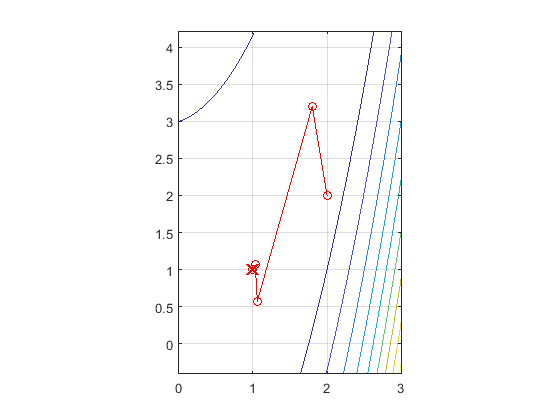

x0 = [2; 2];
tol = 0.00005;

max_iter = 500;
x = x0;
X = [x]; % save the iteration point.
% counter -- time of iteration.
k = 0;
    
% find gradient and hessian matrix.
syms x1 x2
vars = [x1; x2];
% calculate gradient and hessian function of f.
grad = matlabFunction(gradient(f(vars), vars));
hess = matlabFunction(hessian(f(vars), vars));
    
% iteration.
while norm(grad(x(1), x(2))) > tol && k < max_iter
    %for this iteration, calculate gradient and hessian value.
    g = grad(x(1), x(2));
    h = hess(x(1), x(2));
    % calculate update term.
    %s = -h \ g;
    s = -inv(h) * g;
    alpha = 1;
    x = x + s * alpha;
    k = k + 1;
    X = [X, x];
end
y_opt = f(x);

% plot the function and path.
x1_range = linspace(min(X(1,:))-1, max(X(1,:))+1, 1000);
x2_range = linspace(min(X(2,:))-1, max(X(2,:))+1, 1000);
[X1, X2] = meshgrid(x1_range, x2_range);
z = ff(X1,X2);

contour(X1, X2, z);
hold on;
plot(X(1,:), X(2,:), 'r-o');
plot(x(1), x(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
axis equal;
grid on;
hold off;

xlim([0.00 3.00])
ylim([-0.41 4.22])

### (b) Use backtracking line search Newton’s method with initial point $x_0 = (3, 3)^T$ .

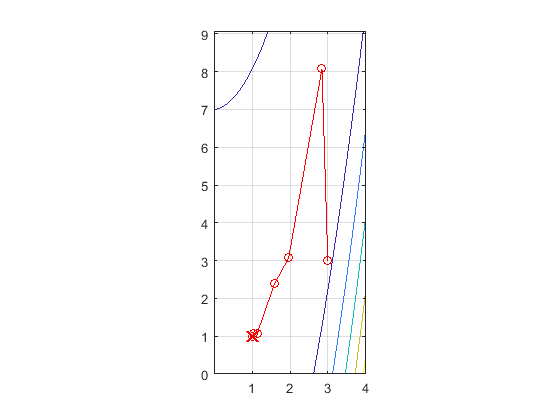

x0 = [3; 3];
tol = 0.00005;

max_iter = 500;
x = x0;
X = [x]; % save the iteration point.
% counter -- time of iteration.
k = 0;
    
% find gradient and hessian matrix.
syms x1 x2
vars = [x1; x2];
% calculate gradient and hessian function of f.
grad = matlabFunction(gradient(f(vars), vars));
hess = matlabFunction(hessian(f(vars), vars));
    
% iteration.
while norm(grad(x(1), x(2))) > tol && k < max_iter
    alpha = 1;
    % for this iteration, calculate gradient and hessian value.
    g = grad(x(1), x(2));
    h = hess(x(1), x(2));
    % calculate update term.
    %s = -h \ g;
    s = -inv(h) * g;
    x_temp = x + s*alpha;
    if f(x_temp) > f(x)
        alpha = alpha / 2;
    end
    x = x + s*alpha;
    X = [X, x]; % save the iteration point.
    k = k + 1;
end
y_opt = f(x);

% plot the function and path.
x1_range = linspace(min(X(1,:))-1, max(X(1,:))+1, 1000);
x2_range = linspace(min(X(2,:))-1, max(X(2,:))+1, 1000);
[X1, X2] = meshgrid(x1_range, x2_range);
z = ff(X1,X2);

contour(X1, X2, z);
hold on;
plot(X(1,:), X(2,:), 'r-o');
plot(x(1), x(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
axis equal;
grid on;
hold off;

### (c) Use damped Newton’s method with initial point $x_0 = (-2, 5)^T$ .

Define variables:

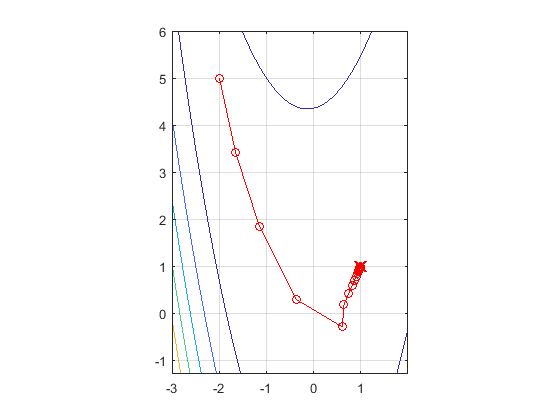

x0 = [-2; 5];
tol = 0.00005;

max_iter = 500;
x = x0;
X = [x]; % save the iteration point.
% counter -- time of iteration.
k = 0;
beta = 0;
    
% find gradient and hessian matrix.
syms x1 x2
vars = [x1; x2];
% calculate gradient and hessian function of f.
grad = matlabFunction(gradient(f(vars), vars));
hess = matlabFunction(hessian(f(vars), vars));
    
% iteration.
while norm(grad(x(1), x(2))) > tol && k < max_iter
    %d = -inv(hess(x))*grad(x);
    % for this iteration, calculate gradient and hessian value.
    g = grad(x(1), x(2));
    h = hess(x(1), x(2));
    % find beta that let H be a positive definite matrix.
    H = h + beta*eye(length(x));
    while all(eig(H) > 0) == false
        beta = beta + 1;
        H = h + beta*eye(length(x));
    end
    
    % calculate the update term.
    d = -H \ g;
    
    % initialize learning rate to 1.
    alpha = 1;
    
    % using line search to find suitable learning rate.
    x_temp = x + d*alpha;
    if f(x_temp) > f(x)
        alpha = alpha / 2;
    end
    x = x + d*alpha;
    X = [X, x];
    k = k + 1;
end
y_opt = f(x);

% plot the function and path.
x1_range = linspace(min(X(1,:))-1, max(X(1,:))+1, 1000);
x2_range = linspace(min(X(2,:))-1, max(X(2,:))+1, 1000);
[X1, X2] = meshgrid(x1_range, x2_range);
z = ff(X1,X2);

contour(X1, X2, z);
hold on;
plot(X(1,:), X(2,:), 'r-o');
plot(x(1), x(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
axis equal;
grid on;
hold off;

### (d) Use rank one quasi-Newton method with initial point $x_0 = (2, 2)^T$ and $B_0 = I$.

Define variables:

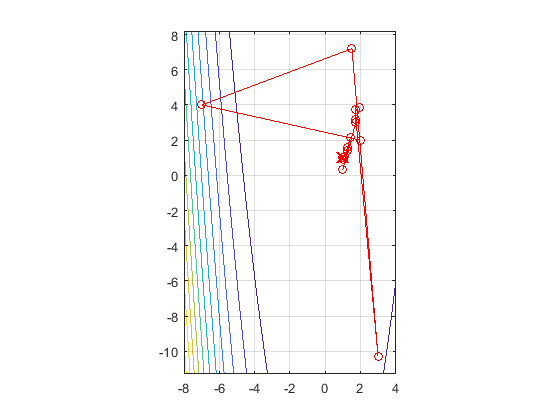

x0 = [2; 2];
B0 = eye(length(x0));
tol = 0.00005;

max_iter = 500;
x = x0;
X = [x]; % save the iteration point.
% counter -- time of iteration.
k = 0;
H = B0;
    
% find gradient and hessian matrix.
syms x1 x2
vars = [x1; x2];
% calculate gradient and hessian function of f.
grad = matlabFunction(gradient(f(vars), vars));

% iteration.
while norm(grad(x(1), x(2))) > tol && k < max_iter
    % learning rate initialization.
    alpha = 1;
    
    % for this iteration, calculate gradient and hessian value.
    g = grad(x(1), x(2));
    
    % calculate the update term.
    p = -H \ g;
    
    % using line search to find suitable learning rate.
    s_temp = alpha * p;
    x_temp = x + s_temp;
    
    % using line search to find alpha.
    if f(x_temp) > f(x)
        alpha = alpha / 2;
    end
    
    s = alpha * p;
    x_next = x + s;
    y = grad(x_next(1), x_next(2)) - g;
    
    % calculate the update term.
    H = H + (y-H*s) * (y-H*s)' / ((y-H*s)' * s);
    %disp(H);
    
    % find next iteration point.
    x = x + s;
    k = k + 1;
    X = [X, x];
end

y_opt = f(x);

% plot the function and path.
x1_range = linspace(min(X(1,:))-1, max(X(1,:))+1, 1000);
x2_range = linspace(min(X(2,:))-1, max(X(2,:))+1, 1000);
[X1, X2] = meshgrid(x1_range, x2_range);
z = ff(X1,X2);

contour(X1, X2, z);
hold on;
plot(X(1,:), X(2,:), 'r-o');
plot(x(1), x(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
axis equal;
grid on;
hold off;

### (e) Use BFGS quasi-Newton method with initial point $x_0 = (2, 2)^T$ and $B_0 = I$.

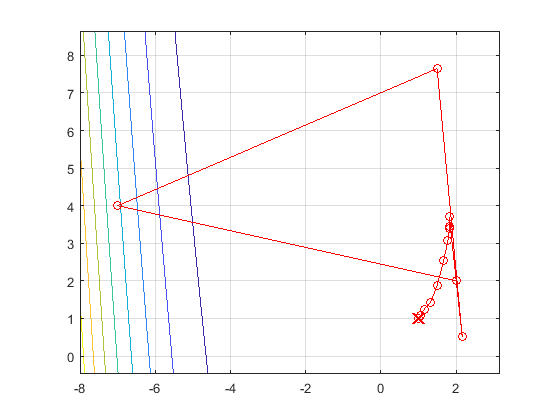

x0 = [2; 2];
B0 = eye(length(x0));
tol = 0.00005;

max_iter = 500;
x = x0;
X = [x]; % save the iteration point.
% counter -- time of iteration.
k = 0;
H = B0;
    
% find gradient and hessian matrix.
syms x1 x2
vars = [x1; x2];
% calculate gradient and hessian function of f.
grad = matlabFunction(gradient(f(vars), vars));
hess = matlabFunction(hessian(f(vars), vars));

% iteration.
while norm(grad(x(1), x(2))) > tol && k < max_iter
    % alpha initialization.
    alpha = 1;
    % for this iteration, calculate gradient and hessian value.
    g = grad(x(1), x(2));
    
    % calculate the update term.
    p = -H \ g;
    
    % using line search to find suitable learning rate.
    s_temp = alpha * p;
    x_temp = x + s_temp;
    if f(x_temp) > f(x)
        alpha = alpha / 2;
    end
    
    s = alpha * p;
    x_next = x + s;
    y = grad(x_next(1), x_next(2)) - g;
    
    % calculate the update term.
    H = H - ((H*s)*(H*s)')/(s'*H*s) + (y*y') / (s'*y);
    
    % find next iteration point.
    x = x + s;
    X = [X, x];
    k = k + 1;
end

y_opt = f(x);

% plot the function and path.
x1_range = linspace(min(X(1,:))-1, max(X(1,:))+1, 1000);
x2_range = linspace(min(X(2,:))-1, max(X(2,:))+1, 1000);
[X1, X2] = meshgrid(x1_range, x2_range);
z = ff(X1,X2);

contour(X1, X2, z);
hold on;
plot(X(1,:), X(2,:), 'r-o');
%plot(1, 1, 'rx', 'MarkerSize', 10, 'LineWidth', 2,  "YData", y_opt);
plot(x(1), x(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
axis equal;
grid on;
hold off;

# Section 2

### 1. Calculate $\nabla \ell$.

    
$$\nabla \ell = (\frac{\partial \ell}{\partial \beta_0}, \frac{\partial \ell}{\partial \beta_1})^T$$


    
$$\frac{\partial \ell}{\partial \beta_0} = \frac{\partial \ell}{\partial p(x)} * \frac{\partial p(x)}{\partial \beta_0$$


          
$$=(\frac{y}{p(x)} + \frac{y-1}{1-p(x)}) p(x) (1-p(x))$$


          
$$= y(1-p(x)) + (y-1)p(x)$$


          
$$=y-p(x)$$


    
$$\frac{\partial \ell}{\partial \beta_1} = \frac{\partial \ell}{\partial p(x)} * \frac{\partial p(x)}{\partial \beta_1$$


          
$$=(\frac{y}{p(x)} + \frac{y-1}{1-p(x)}) xp(x) (1-p(x))$$


          
$$= xy(1-p(x)) + (y-1)p(x)$$


          
$$= x(y-p(x))$$


    
$$\therefore \nabla \ell =\left[
\begin{array}{l}
y-p(x)\\
x(y-p(x))
\end{array}
\right]$$


### 2. Calculate $\nabla \ell^2$.

    
$$\nabla \ell^2 = \left[
\begin{array}{l}
\frac{\partial^2 \ell}{\partial \beta_0^2} & \frac{\partial^2 \ell}{\partial \beta_0 \beta_1}\\
\frac{\partial^2 \ell}{\partial \beta_0 \beta_1} & \frac{\partial^2 \ell}{\partial \beta_1^2}
\end{array}
\right]$$$


           
$$= \left[
\begin{array}{l}
\frac{\partial(y-p(x))}{\partial p(x)}*\frac{\partial p(x)}{\partial \beta_0} & \frac{\partial(y-p(x))}{\partial p(x)}*\frac{\partial p(x)}{\partial \beta_1}\\
\frac{\partial(x(y-p(x)))}{\partial p(x)}*\frac{\partial p(x)}{\partial \beta_0} & \frac{\partial(x(y-p(x)))}{\partial p(x)}*\frac{\partial p(x)}{\partial \beta_1}
\end{array}
\right]$$


           
$$= \left[
\begin{array}{l}
-p(x)(1-p(x)) & -xp(x)(1-p(x))\\
-xp(x)(1-p(x)) & -x^2p(x)(1-p(x))
\end{array}
\right]$$


# Section 3

### 1. verify (1)

    According to the question, we have:

        
$$\ell = \sum_{k:y_k=1}{\ln{(p_k)}} + \sum_{k:y_k=0}{\ln{(1-p_k)}}$$


    Since $y_k$'s value either be 1 or 0, therefore we have:

        
$$\sum_{k:y_k=1}{\ln{(p_k)}}=\sum^K_{k=1}{y_k\ln{(p_k)}}$$


    Since when $y_k=0$, we have:

        
$$\sum_{k:y_k=0}{\ln{(p_k)}}=\sum^K_{k=0}{y_k\ln{(p_k)}}=0$$


    Therefore, submission only take the condition that $y_k=1$ into consideration.

    We can do the same transformation to the other term, that is:

        
$$\sum_{k:y_k=0}{\ln{(1-p_k)}}=\sum^K_{k=1}{(1-y_k)\ln{(1-p_k)}}$$


    And therefore,

        
$$\ell = \sum^K_{k=1}{y_k\ln{(p_k)}} + \sum^K_{k=1}{(1-y_k)\ln{(1-p_k)}} = \sum^K_{k=1}{(y_k\ln{(p_k)}+(1-y_k)\ln{(1-p_k)})}$$


    (1) is verified.

### 2. Calculate $\nabla \ell$.

    
$$\nabla \ell = (\frac{\partial \ell}{\partial \beta_0}, \frac{\partial \ell}{\partial \beta_1})^T$$


    
$$\frac{\partial \ell}{\partial \beta_0} = \sum^K_{k=1}{\frac{\partial \ell}{\partial p_k} * \frac{\partial p_k}{\partial \beta_0}$$


          
$$=\sum^K_{k=1}{\frac{(y_k-1)e^{-(\beta_0+\beta_1 x_k)}+y_k}{1+e^{-(\beta_0+\beta_1 x)}}}$$


          
$$=\sum^K_{k=1}{(\frac{y_k}{p_k} + \frac{y_k-1}{1-p_k}) p_k (1-p_k)}$$


          
$$= \sum^K_{k=1}{y(1-p_k) + (y_k-1)p_k}$$


          
$$=\sum^K_{k=1}{y-p_k}$$


    
$$\frac{\partial \ell}{\partial \beta_1} = \sum^K_{k=1}{\frac{\partial \ell}{\partial p_k} * \frac{\partial p_k}{\partial \beta_1}$$


          
$$=\sum^K_{k=1}{x_k (\frac{(y_k-1)e^{-(\beta_0+\beta_1 x_k)}+y_k}{1+e^{-(\beta_0+\beta_1 x)}})}$$


          
$$=\sum^K_{k=1}{(\frac{y_k}{p_k} + \frac{y_k-1}{1-p_k}) xp_k (1-p_k)}$$


          
$$= \sum^K_{k=1}{xy_k(1-p_k) + (y_k-1)p_k}$$


          
$$= \sum^K_{k=1}{x(y_k-p_k)}$$


    
$$\therefore \nabla \ell =\left[
\begin{array}{l}
\sum^K_{k=1}{y_k-p_k}\\
\sum^K_{k=1}{x(y_k-p_k)}
\end{array}
\right]$$


### 3. Calculate $\nabla \ell^2$.

    
$$\nabla \ell^2 = \left[
\begin{array}{l}
\frac{\partial^2 \ell}{\partial \beta_0^2} & \frac{\partial^2 \ell}{\partial \beta_0 \beta_1}\\
\frac{\partial^2 \ell}{\partial \beta_0 \beta_1} & \frac{\partial^2 \ell}{\partial \beta_1^2}
\end{array}
\right]$$$

$$= \left[
\begin{array}{l}
\sum^K_{k=1}{\frac{\partial(y-p_k)}{\partial p_k}*\frac{\partial p_k}{\partial \beta_0}} & \sum^K_{k=1}{\frac{\partial(y-p_k)}{\partial p_k}*\frac{\partial p_k}{\partial \beta_1}}\\
\sum^K_{k=1}{\frac{\partial(x(y-p_k))}{\partial p_k}*\frac{\partial p_k}{\partial \beta_0}} & \sum^K_{k=1}{\frac{\partial(x(y-p_k))}{\partial p_k}*\frac{\partial p_k}{\partial \beta_1}}
\end{array}
\right]$$


    
$$\frac{\partial^2 \ell}{\partial \beta_0^2} = \frac{\partial}{\partial \beta_0}\frac{\partial \ell}{\partial \beta_0}\\ = 
\frac{\partial \ell}{\partial \beta_0}\sum^K_{k=1}{\frac{(y_k-1)e^{-(\beta_0+\beta_1 x_k)}+y_k}{1+e^{-(\beta_0+\beta_1 x)}}}\\=
\sum^K_{k=1}{\frac{-e^{-(\beta_0+\beta_1 x_k)}}{\left(1+e^{-(\beta_0+\beta_1 x)}\right)^2}}\\=
\sum^K_{k=1}{-p_k(1-p_k)}$$


    
$$$\frac{\partial^2 \ell}{\partial \beta_0 \partial \beta_1} = \frac{\partial}{\partial \beta_1}\frac{\partial \ell}{\partial \beta_0}\\ = 
\frac{\partial \ell}{\partial \beta_1}\sum^K_{k=1}{\frac{(y_k-1)e^{-(\beta_0+\beta_1 x_k)}+y_k}{1+e^{-(\beta_0+\beta_1 x)}}}\\=
\sum^K_{k=1}{\frac{-x_k e^{-(\beta_0+\beta_1 x_k)}}{\left(1+e^{-(\beta_0+\beta_1 x)}\right)^2}}\\=
\sum^K_{k=1}{-x_k(1-p_k)}$$$


    
$$$\frac{\partial^2 \ell}{\partial \beta_1^2} = \frac{\partial}{\partial \beta_1}\frac{\partial \ell}{\partial \beta_1}\\ = 
\frac{\partial \ell}{\partial \beta_1}\sum^K_{k=1}{\frac{x_k\left((y_k-1)e^{-(\beta_0+\beta_1 x_k)}+y_k\right)}{1+e^{-(\beta_0+\beta_1 x)}}}\\=
\sum^K_{k=1}{\frac{-x_k^2 e^{-(\beta_0+\beta_1 x_k)}}{\left(1+e^{-(\beta_0+\beta_1 x)}\right)^2}}\\=
\sum^K_{k=1}{-x^2p_k(1-p_k)}$  $$



$$\therefore \nabla \ell^2= \left[
\begin{array}{l}
\sum^K_{k=1}{-p_k(1-p_k)} & \sum^K_{k=1}{-xp_k(1-p_k)}\\
\sum^K_{k=1}{-xp_k(1-p_k)} & \sum^K_{k=1}{-x^2p_k(1-p_k)}
\end{array}
\right]$$


### 4. Use the given data, write a Newton methods to fit the data, make a contour plot to denote how the solutions converge in the β0 − β1 plan.

% array used to store data.
Hours = [0.5 0.75 1.0 1.25 1.5 1.75 1.75 2.0 2.25 2.5 2.75 3.0 3.25 3.5 4.0 4.25 4.5 4.75 5.0 5.5]';
Pass = [0 0 0 0 0 0 1 0 1 0 1 0 1 0 1 1 1 1 1 1]';
b0 = [0; 0];
tol = 10^-6;

f = @(beta) -sum(Pass.*log(1./(1+exp(-beta(1)-beta(2)*Hours))) + (1-Pass).*log(1-1./(1+exp(-beta(1)-beta(2)*Hours))));
 
%define the maximum iteration time.
max_iter = 500;
% initialize x using x0, the initial point.
b = b0;
% save the iteration point.
B = [b'];
% counter -- time of iteration.
k = 0;
    
% find gradient and hessian matrix.
syms b0 b1
vars = [b0; b1];
% calculate gradient and hessian function of f.
grad = matlabFunction(gradient(f(vars), vars));
hess = matlabFunction(hessian(f(vars), vars));
    
% iteration.
while norm(grad(b(1), b(2))) > tol && k < max_iter
    %for this iteration, calculate gradient and hessian value.
    g = grad(b(1), b(2));
    h = hess(b(1), b(2));
    % calculate update term.
    %s = -h \ g;
    s = -inv(h) * g;
    alpha = 1;
    b = b + s*alpha;
    B = [B, b'];
    k = k + 1;
end
y_opt = f(b);
b, k, y_opt

b =    -4.0777
    1.5046


k = 5

y_opt = 0.4015

% % plot the function and path.
% ff = @(bb1, bb2) -sum(Pass.*log(1./(1+exp(-bb1-bb2.*Hours))) + (1-Pass).*log(1-1./(1+exp(-bb1-bb2.*Hours))));
% b1_range = linspace(min(B(1,:))-1, max(B(1,:))+1, 1000);
% b2_range = linspace(min(B(2,:))-1, max(B(2,:))+1, 1000);
% [B1, B2] = meshgrid(b1_range, b2_range);
% z = ff(B1,B2);
% 
% contour(B1, B2, z);
% hold on;
% plot(B(1,:), B(2,:), 'r-o');
% plot(b(1), b(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
% axis equal;
% grid on;
% hold off;

### 5. Specify that how you choose the initial values.

Here I implement Golden Search Method to find a point that near optimal point.

% Define the function to minimize
f = @(beta) -sum(Pass.*log(1./(1+exp(-beta(1)-beta(2)*Hours))) + (1-Pass).*log(1-1./(1+exp(-beta(1)-beta(2)*Hours))));

% Set the initial interval for golden search
a = 0;
b = 6;

% Set the tolerance level for golden search
tol = 1e-6;

% Set up the golden ratio
golden_ratio = (sqrt(5)-1)/2;

% Define the two intermediate points
x1 = b - golden_ratio*(b-a);
x2 = a + golden_ratio*(b-a);

% Evaluate the function at the two intermediate points
f1 = f([x1, 0]);
f2 = f([x2, 0]);

% While the interval is larger than the tolerance level
while (b-a) > tol
    % If f1 is less than f2, update b
    if f1 < f2
        b = x2;
        x2 = x1;
        f2 = f1;
        x1 = b - golden_ratio*(b-a);
        f1 = f([x1, 0]);
    % Otherwise, update a
    else
        a = x1;
        x1 = x2;
        f1 = f2;
        x2 = a + golden_ratio*(b-a);
        f2 = f([x2, 0]);
    end
end

beta_0_init = (a+b)/2; % Use the midpoint of the interval as the initial point for beta_0

% Reset the interval for golden search
a = 0;
b = 6;

% Define the two intermediate points
x1 = b - golden_ratio*(b-a);
x2 = a + golden_ratio*(b-a);

% Evaluate the function at the two intermediate points
f1 = f([beta_0_init, x1]);
f2 = f([beta_0_init, x2]);

% While the interval is larger than the tolerance level
while (b-a) > tol
    % If f1 is less than f2, update b
    if f1 < f2
        b = x2;
        x2 = x1;
        f2 = f1;
        x1 = b - golden_ratio*(b-a);
        f1 = f([beta_0_init, x1]);
    % Otherwise, update a
    else
        a = x1;
        x1 = x2;
        f1 = f2;
        x2 = a + golden_ratio*(b-a);
        f2 = f([beta_0_init, x2]);
    end
end

beta_1_init = (a+b)/2; % Use the midpoint of the interval as the initial point for beta_1

beta_init = [beta_0_init, beta_1_init]; % Combine the initial points for beta_0 and beta_1
disp(beta_init);

    0.0000    0.2179



% function [a, b] = golden_search(f, a, b, tol)
% % golden_search: perform golden search to minimize a function on the interval [a, b]
% % Input:
% % - f: a function handle that takes a scalar input and returns a scalar output
% % - a, b: the interval to search for the minimum, with a < b
% % - tol: tolerance level for the search
% % Output:
% % - a, b: the updated interval containing the minimum
% 
%     % Set up the golden ratio
%     golden_ratio = (sqrt(5)-1)/2;
%     
%     % Define the two intermediate points
%     x1 = b - golden_ratio*(b-a);
%     x2 = a + golden_ratio*(b-a);
%     
%     % Evaluate the function at the two intermediate points
%     f1 = f(x1);
%     f2 = f(x2);
%     
%     % While the interval is larger than the tolerance level
%     while (b-a) > tol
%         % If f1 is less than f2, update b
%         if f1 < f2
%             b = x2;
%             x2 = x1;
%             f2 = f1;
%             x1 = b - golden_ratio*(b-a);
%             f1 = f(x1);
%         % Otherwise, update a
%         else
%             a = x1;
%             x1 = x2;
%             f1 = f2;
%             x2 = a + golden_ratio*(b-a);
%             f2 = f(x2);
%         end
%     end
% end
% 
% % Define the function to minimize
% logistic_loss = @(beta) -mean(y.*log(1./(1+exp(-beta(1)-beta(2)*x))) + (1-y).*log(1-1./(1+exp(-beta(1)-beta(2)*x))));
% 
% % Set the initial interval for golden search
% a = -10;
% b = 10;
% 
% % Set the tolerance level for golden search
% tol = 1e-6;
% 
% % Perform golden search to find the minimum of the logistic_loss function
% [~, beta_0_init] = golden_search(@(beta_0) f([beta_0, 0]), a, b, tol);
% [~, beta_1_init] = golden_search(@(beta_1) f([beta_0_init, beta_1]), a, b, tol);
% beta_init = [beta_0_init, beta_1_init];

% a = 0;
% b = 6;
% 
% r = 0.618;
% e = 10^-6;
% u = b - r*(b-a);
% v = a + r*(b-a);
% while abs(b-a) > e
%     fu = subs(f, u);
%     fv = subs(f, v);
%     if fu < fv
%         a = a;
%         b = v;
%         v = u;
%         u = b - r*(b-a);
%     else if fu > fv
%             a = u;
%             b = b;
%             u = v;
%             v = a + r*(b-a);
%         else
%             a = u;
%             b = v;
%             u = b - r*(b-a);
%             v = a + r*(b-a);
%         end
%     end
% end
% xmin = (a+b) * 0.5;
% fx = subs(f, xmin);

### 6. Compare your results with other fitting tool box, and write your own logistic regression program which can work versatily with as little as human interactions.

Here I used logistic regression package in Matlab, and we can got value same as previous one.

Hours = [0.5 0.75 1.0 1.25 1.5 1.75 1.75 2.0 2.25 2.5 2.75 3.0 3.25 3.5 4.0 4.25 4.5 4.75 5.0 5.5]';
Pass = [0 0 0 0 0 0 1 0 1 0 1 0 1 0 1 1 1 1 1 1]';

b = glmfit(Hours, [Pass ones(20, 1)], 'binomial', 'link', 'logit');
disp(b);

   -4.0777
    1.5046

